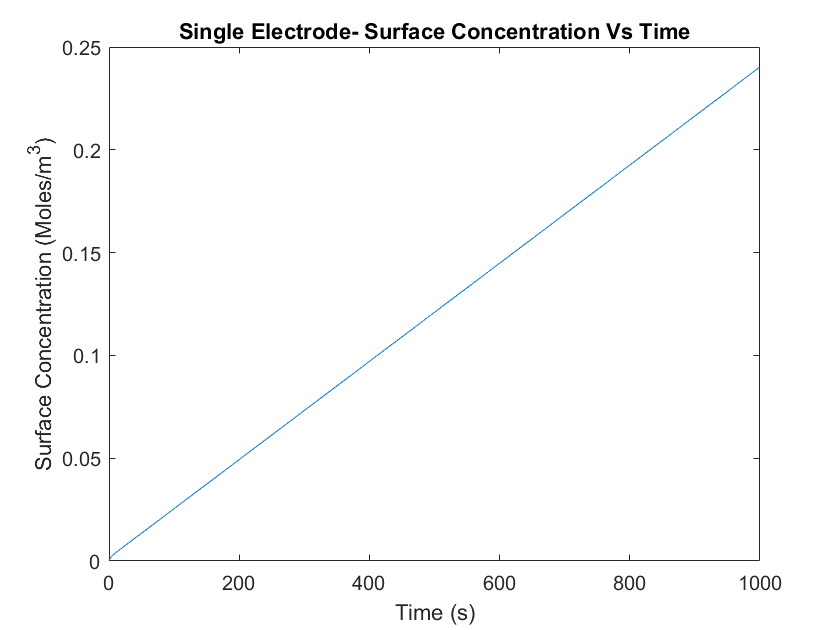

%Step 5 and 6

%Radius
R=10;
%Diffusivity
D=1;
nSteps=1000;
dt=1;

t=(0:dt:nSteps-1)';
u=ones(nSteps,1);
u_sin=sin(t/(10*pi));

%Initial Conditions
y1_0 = 0;
y2_0 =0;
sigmaY=0;

%Constant Input
y=lithium_model(R, D, u, y1_0, y2_0, dt, sigmaY);
plot(t, y)
title("Single Electrode- Surface Concentration Vs Time")
xlabel("Time (s)")
ylabel("Surface Concentration (Moles/m^3)")

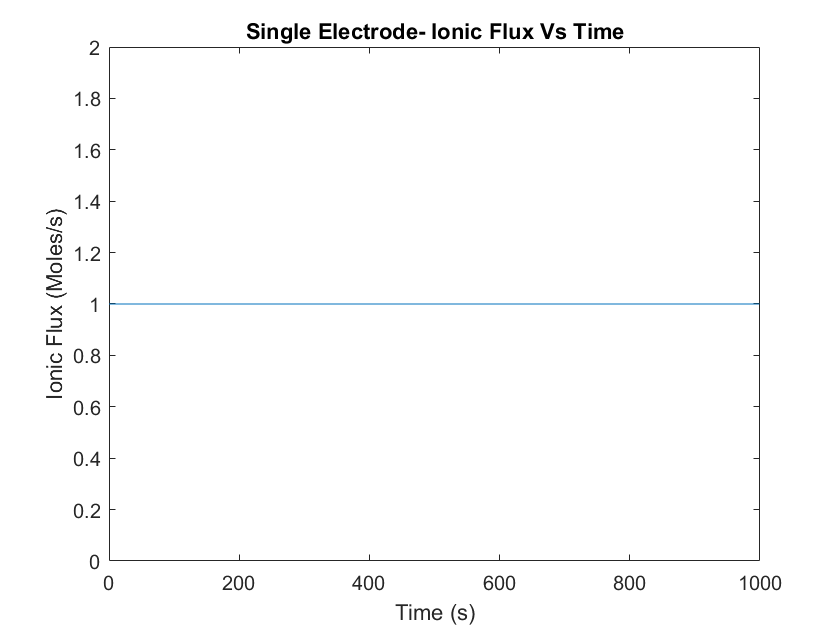


plot(t,u)
title("Single Electrode- Ionic Flux Vs Time")
xlabel("Time (s)")
ylabel("Ionic Flux (Moles/s)")

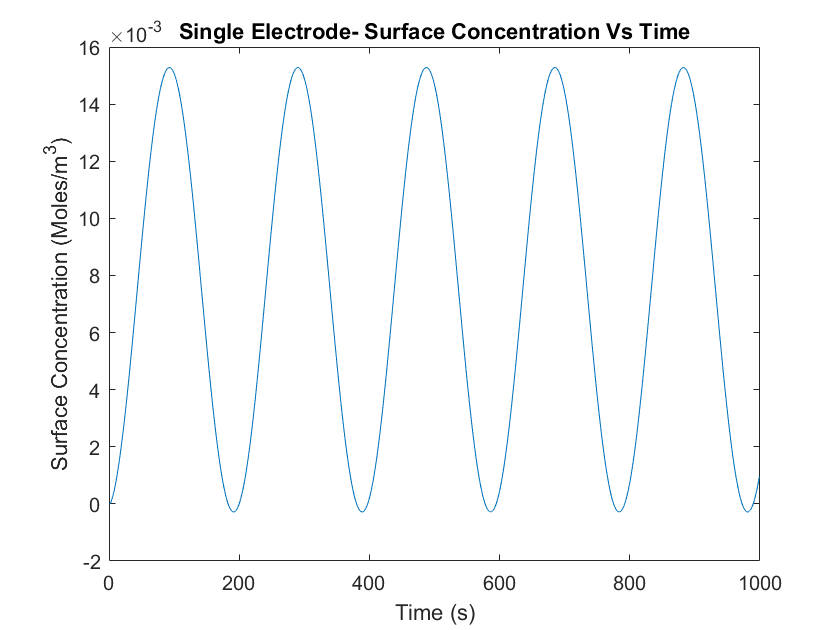


%Sinusoidal Input
y=lithium_model(R, D, u_sin, y1_0, y2_0, dt, sigmaY);
plot(t, y)
title("Single Electrode- Surface Concentration Vs Time")
xlabel("Time (s)")
ylabel("Surface Concentration (Moles/m^3)")

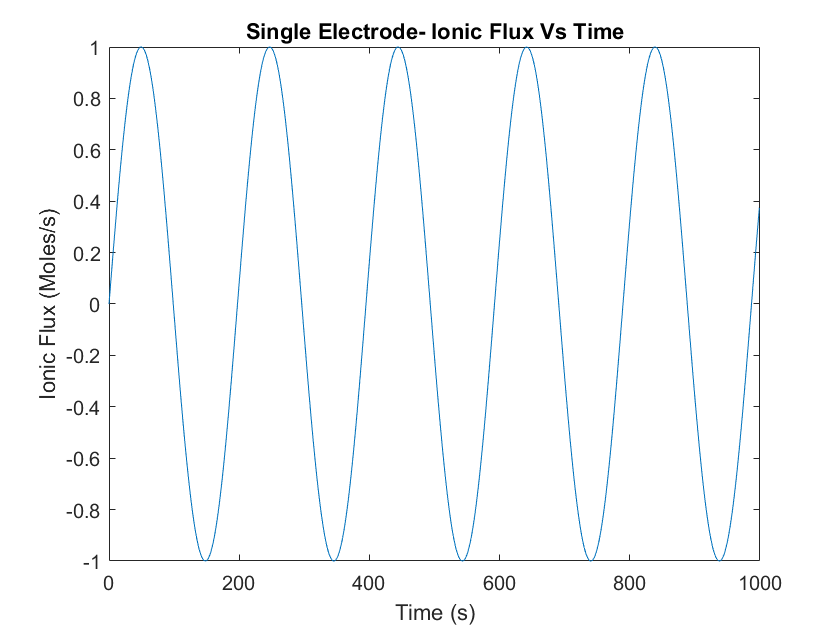


plot(t,u_sin)
title("Single Electrode- Ionic Flux Vs Time")
xlabel("Time (s)")
ylabel("Ionic Flux (Moles/s)")


%Step 7:

disp("As you insert charge into the battery, and electrons leave the anode, Lithium ions will convert to the ionic state an therefore increase the concentration of anode")

As you insert charge into the battery, and electrons leave the anode, Lithium ions will convert to the ionic state an therefore increase the concentration of anode


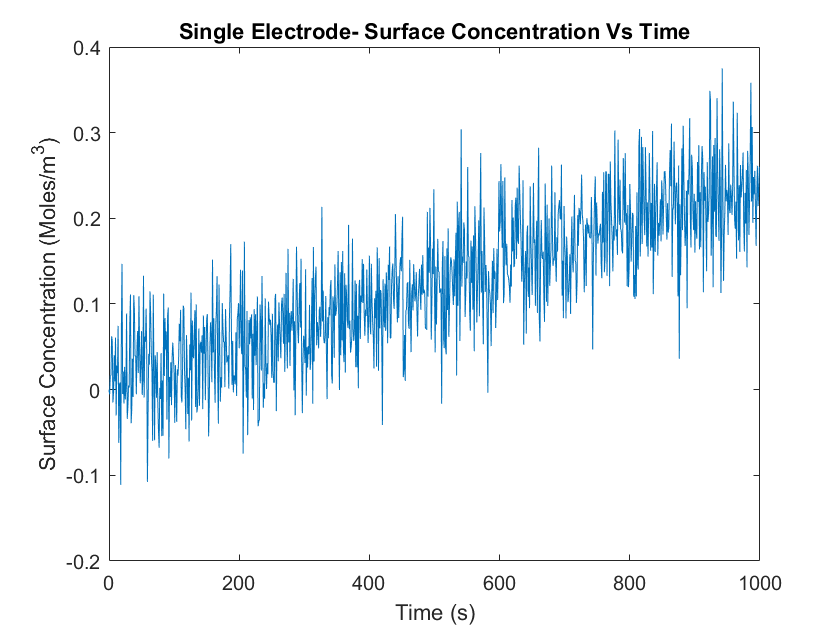


%Step 8:

%Independent, Identically Distributed, Zero-mean, Gaussian Noise

%Constant Input
sigmaY = 0.05;
y_noise = lithium_model(R, D, u, y1_0, y2_0, dt, sigmaY);
plot(t,y_noise)
title("Single Electrode- Surface Concentration Vs Time")
xlabel("Time (s)")
ylabel("Surface Concentration (Moles/m^3)")

plot(t,u)
title("Single Electrode- Ionic Flux Vs Time")
xlabel("Time (s)")
ylabel("Ionic Flux (Moles/s)")

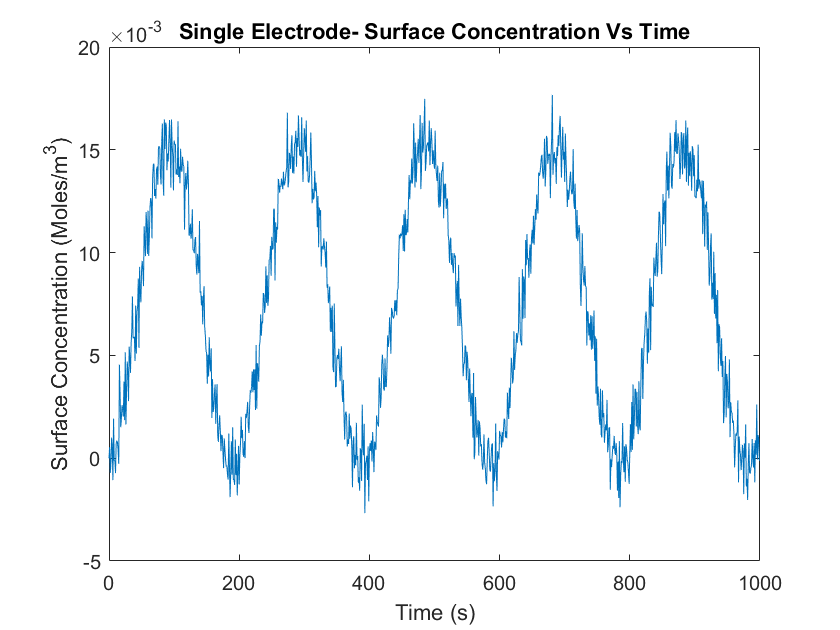


%Sinusoidal Input
sigmaY = 0.001;
y_noise = lithium_model(R, D, u_sin, y1_0, y2_0, dt, sigmaY);
plot(t,y_noise)
title("Single Electrode- Surface Concentration Vs Time")
xlabel("Time (s)")
ylabel("Surface Concentration (Moles/m^3)")

plot(t,u_sin)
title("Single Electrode- Ionic Flux Vs Time")
xlabel("Time (s)")
ylabel("Ionic Flux (Moles/s)")



%Step 9:
clear all

Rtrue = 10;
Dtrue = 1;
N = 1000;
deltaT= 1;
sigmaY = 0.005;
u = ones(N,1);
y1_0 = 0;
y2_0 = 0;

yhat = lithium_model(Rtrue, Dtrue, u, y1_0, y2_0, deltaT, 0);

Rguess = 30;
Dguess = 8;
thetaGuess(1) = Rguess;
thetaGuess(2) = Dguess;

optimFunction = @(theta)(LSP(theta, Rtrue, Dtrue, u, N, deltaT, yhat, y1_0, y2_0, sigmaY));
varEstimation=fminsearch(optimFunction,thetaGuess)

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.022178 



varEstimation =     9.9547    5.3218



disp("My parameter esimates appear to be unbiased as .... I am unsatisfied mith the estimated accuracy because ..")

My parameter esimates appear to be unbiased as .... I am unsatisfied mith the estimated accuracy because ..



%Step 10:

nMonteCarlo= 10;

for i=1:nMonteCarlo
    optimFunction = @(theta)(LSP(theta, Rtrue, Dtrue, u, N, deltaT, yhat, y1_0, y2_0, sigmaY));
    bestTheta=fminsearch(optimFunction,thetaGuess);
    RMonteCarlo(i) = bestTheta(1);
    DMonteCarlo(i) = bestTheta(2);
end

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.022682 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 0.022150 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 6.801471 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 3.957947 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 8.165722 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: 8.137888 

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase 

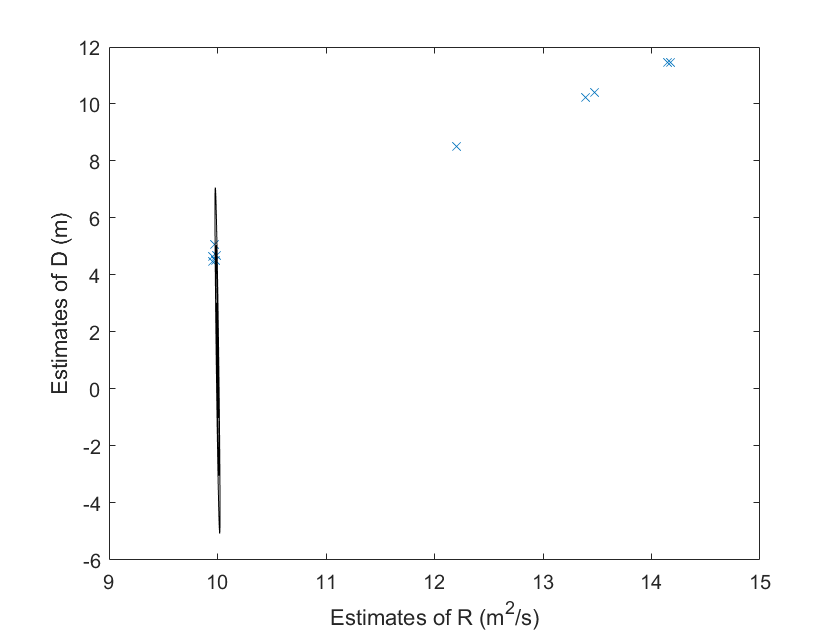



plot(RMonteCarlo, DMonteCarlo, 'x')
xlabel('Estimates of R (m^2/s)')
ylabel('Estimates of D (m)')
yNominal = lithium_model(Rtrue, Dtrue ,u, y1_0, y2_0, deltaT, 0);
epsilon = 1e-4;

y1 = lithium_model(Rtrue*(1+epsilon), Dtrue, u, y1_0, y2_0, deltaT, 0);
y2 = lithium_model(Rtrue, Dtrue*(1+epsilon), u, y1_0, y2_0, deltaT, 0);

s1 = (y1-yNominal)/(Rtrue*epsilon);
s2 = (y2-yNominal)/(Rtrue*epsilon);

S= zeros(length(s1), 2);
S(:,1) = s1;
S(:,2) = s2;

F = (1/(sigmaY^2))*(S')*S;
CRLB = inv(F);
[V, D] = eig(CRLB);
lambda1 = D(1,1);
lambda2 = D(2,2);
v1 = V(:,1);
v2 = V(:,2);

xprime = linspace(-sqrt(lambda1),sqrt(lambda1));
yprime = sqrt((1-(xprime.^2)/lambda1)*lambda2);

xypoints = [Rtrue;Dtrue]+v1*xprime+v2*yprime;
xypointsRef = [Rtrue;Dtrue]+v1*xprime-v2*yprime;
xy2points = [Rtrue;Dtrue]+2*v1*xprime+2*v2*yprime;
xy2pointsRef = [Rtrue;Dtrue]+2*v1*xprime-2*v2*yprime;
xy3points = [Rtrue;Dtrue]+3*v1*xprime+3*v2*yprime;
xy3pointsRef = [Rtrue;Dtrue]+3*v1*xprime-3*v2*yprime;

hold on

plot(xypoints(1,:), xypoints(2,:), 'k')
plot(xypointsRef(1,:), xypointsRef(2,:), 'k')
plot(xy2points(1,:), xy2points(2,:), 'k')
plot(xy2pointsRef(1,:), xy2pointsRef(2,:), 'k')
plot(xy3points(1,:), xy3points(2,:), 'k')
plot(xy3pointsRef(1,:), xy3pointsRef(2,:), 'k')

function y = lithium_model(R, D, u, y1_0, y2_0, dt, sigmaY)
%Pre-Allocation
nSteps = length(u);
y1=zeros(nSteps,1);
y2=zeros(nSteps,1);
y=zeros(nSteps,1);

%Initial Conditions
y1dot(1)=y1_0;
y2(1)=y2_0;

%PADE Second Order Approximation
%Transfer Function Coefficients

m=-1/(4*pi*R^2*D);
a=(-3*D*m)/R;
b=-(2*m*R)/7;
c=R^2/(35*D);

%Foward Euler
for i=2:nSteps
    y1(i)=y1(i-1)+a*u(i-1)*dt;
    y2(i)=y2(i-1)+((b-c*a)/c)*u(i-1)*dt-(1/c)*y2(i-1)*dt;
    y(i)=(y1(i)+y2(i))+sigmaY*randn(1);
end
return
end

function error = LSP(theta, Rexact, Dexact, u, nSteps, dt, yhat, y1_0, y2_0, sigmaY)

nSteps = 1000;
R = theta(1);
D = theta(2);

y = lithium_model(R, D, u, y1_0, y2_0, dt, sigmaY);

error = 0;

for i=1:nSteps
    error = error + (yhat(i)-y(i))^2;
end

end








